### Prueba de Ruido Perlin en 1D

%Persistencia
p = 0.6;
%Octavas 
octaves = 8;


perlinNoiseGenerator = PerlinNoiseGenerator(p, octaves);
t = 1:1000;
noise = [];
for i = 1:length(t)
    noise = [noise, perlinNoiseGenerator.perlinNoise(t(i)*0.01)];
end
f = figure()

f =   Figure (27) with properties:

      Number: 27
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


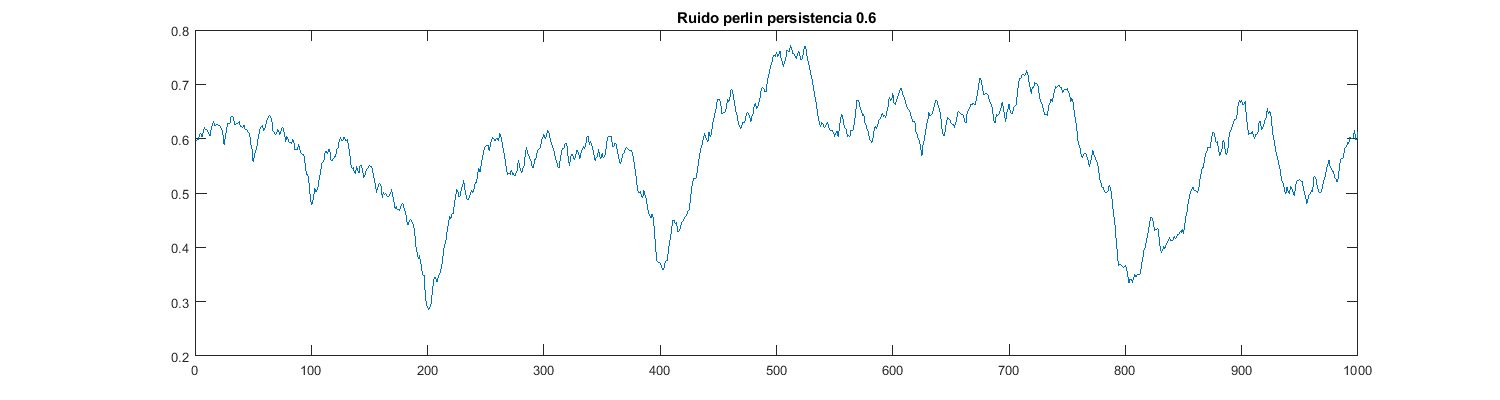

f.Position = [100 100 1500 400];
plot(t, noise)
title("Ruido perlin persistencia " + string(p))

### Histograma de ruido Perlin

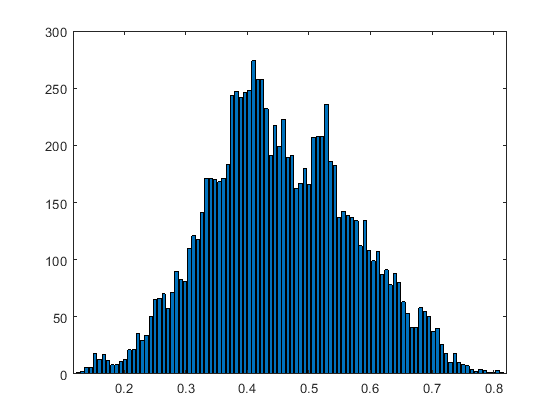

histogramCalculator = Histogram();

[xVals, hist] = histogramCalculator.computeHistogram(noise);
figure()
bar(xVals, hist)

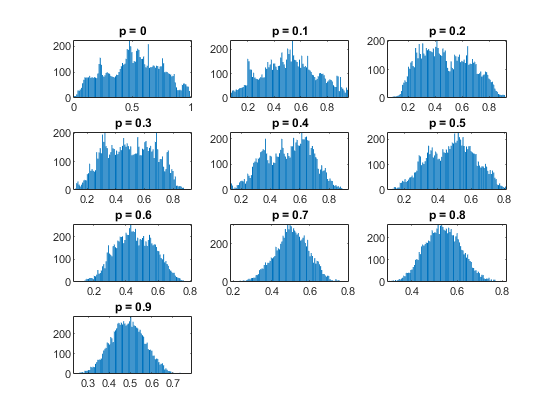

f = figure();
pValues = linspace(0,0.9,10);
octaves = 10;
histogramCalculator = Histogram();
for i = 1:length(pValues)
    p = pValues(i);
    perlinNoiseGenerator = PerlinNoiseGenerator(p, octaves);
    t = 1:10000;
    noise = zeros(length(t), 1);
    for j = 1:length(t)
      noise(j) = perlinNoiseGenerator.perlinNoise(t(j)*0.01);
    end
    [xVals, hist] = histogramCalculator.computeHistogram(noise);
    subplot(4,3,i)
    bar(xVals, hist, 'EdgeColor', 'none')
    title("p = "+string(p))
end

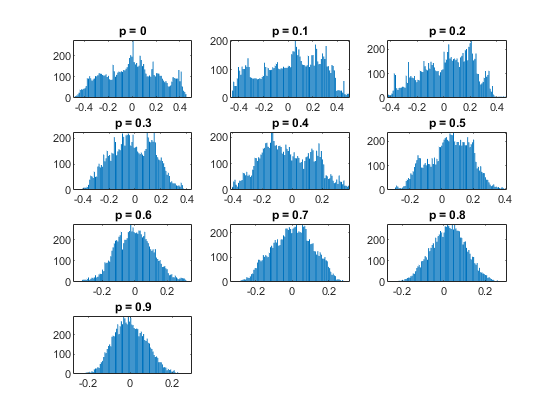

f = figure();
pValues = linspace(0,0.9,10);
octaves = 10;
histogramCalculator = Histogram();
for i = 1:length(pValues)
    p = pValues(i);
    perlinNoiseGenerator = PerlinNoiseGenerator(p, octaves);
    t = 1:10000;
    noise = zeros(length(t), 1);
    for j = 1:length(t)
      noise(j) = perlinNoiseGenerator.translatedPerlinNoise(t(j)*0.01, -0.5, 0.5);
    end
    [xVals, hist] = histogramCalculator.computeHistogram(noise);
    subplot(4,3,i)
    bar(xVals, hist, 'EdgeColor', 'none')
    title("p = "+string(p))
end

### Perlin Noise 2D

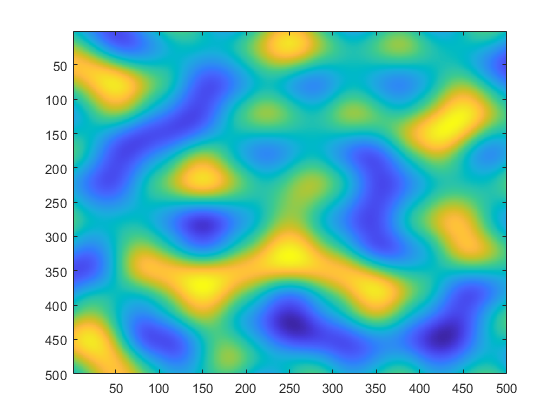

n = 500;
m = 500;
xVals = linspace(0,50,m);
yVals = linspace(0,50,n);
noiseGrid = zeros(n,m);
octaves = 10;
persistance = 0.5;
perlinNoiseGen2D = PerlinNoise2DGenerator(persistance, octaves);
for i = 1:n
    for j = 1:m
        noiseGrid(i,j) = perlinNoiseGen2D.computePerlinNoise(i*0.01, j*0.01);
    end
end


figure()
imagesc(noiseGrid)

%imagesc(xVals, yVals, noiseGrid)


%Obtengamos el ruido completo con octavas
octaves = 8;
persistance = 0.5;

noiseGrid = zeros(n,m);
perlinNoiseGen2D = PerlinNoise2DGenerator(persistance, octaves);
for i = 1:n
    for j = 1:m
        noiseGrid(i,j) = perlinNoiseGen2D.getCompletePerlinNoise(i*0.005, j*0.005);
    end
end


figure()
imagesc(noiseGrid)

### Dibujo ruidio Perlin 

%set(gca, 'gridalpha', 1)

nSeeds = 2000;
octaves = 8;
persistance = 0.5;
frequency = 0.005;
perlinDrawer = PerlinNoiseDrawer(nSeeds, octaves, persistance, frequency);


h =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


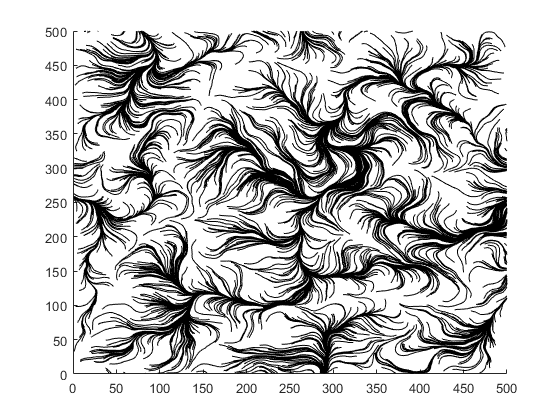

nSteps = 1000;
deltaT = 0.5;
grid off
axis off
perlinDrawer.drawMovement(nSteps, deltaT);

h =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


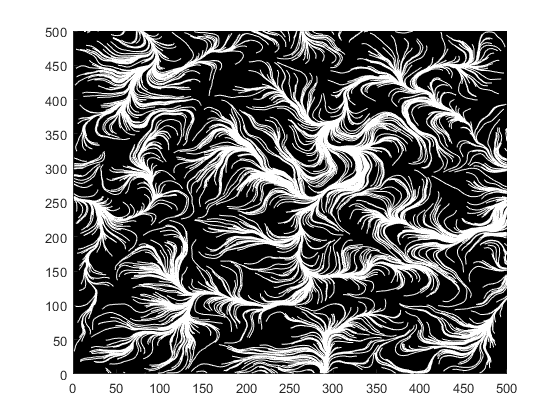

nSteps = 1000;
deltaT = 0.5;
perlinDrawer.drawMovementBlackBackground(nSteps, deltaT);

### Generador de paisajes

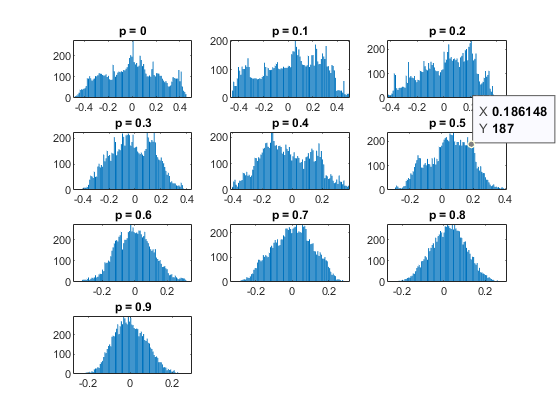

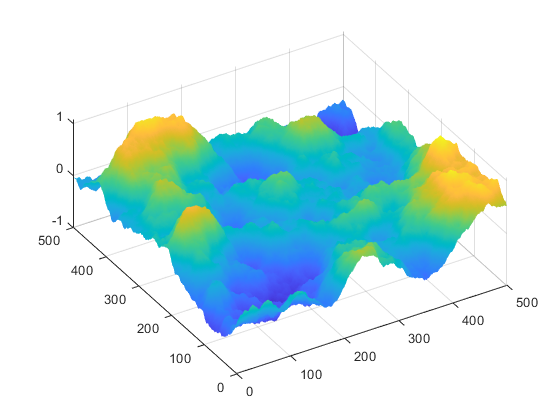


octaves = 8;
persistance = 0.5;
landGenerator = LandscapeGenerator(persistance, octaves);
landGenerator.buildLandscape(500, 500);